# Using ActiveContour

Activecontour is a way to perform segmentation on an image. In our case it doesn't really help segmenting the arms 

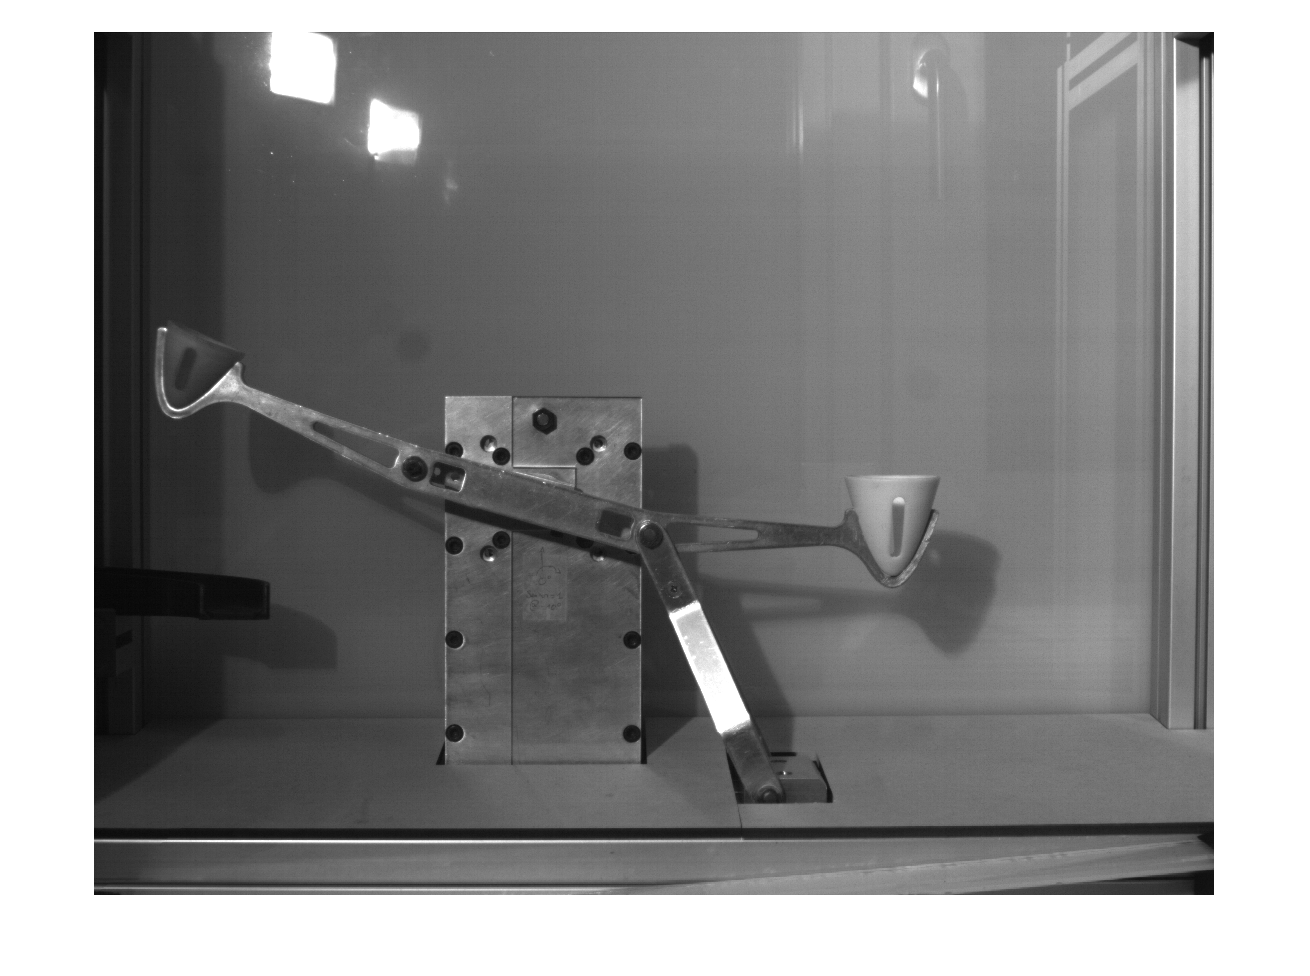

frame = load('Ballenwerper_sync_380fps_006.npychunk_3.mat').video_data(1,:,:);
frame = squeeze(frame);
figure, imshow(frame)

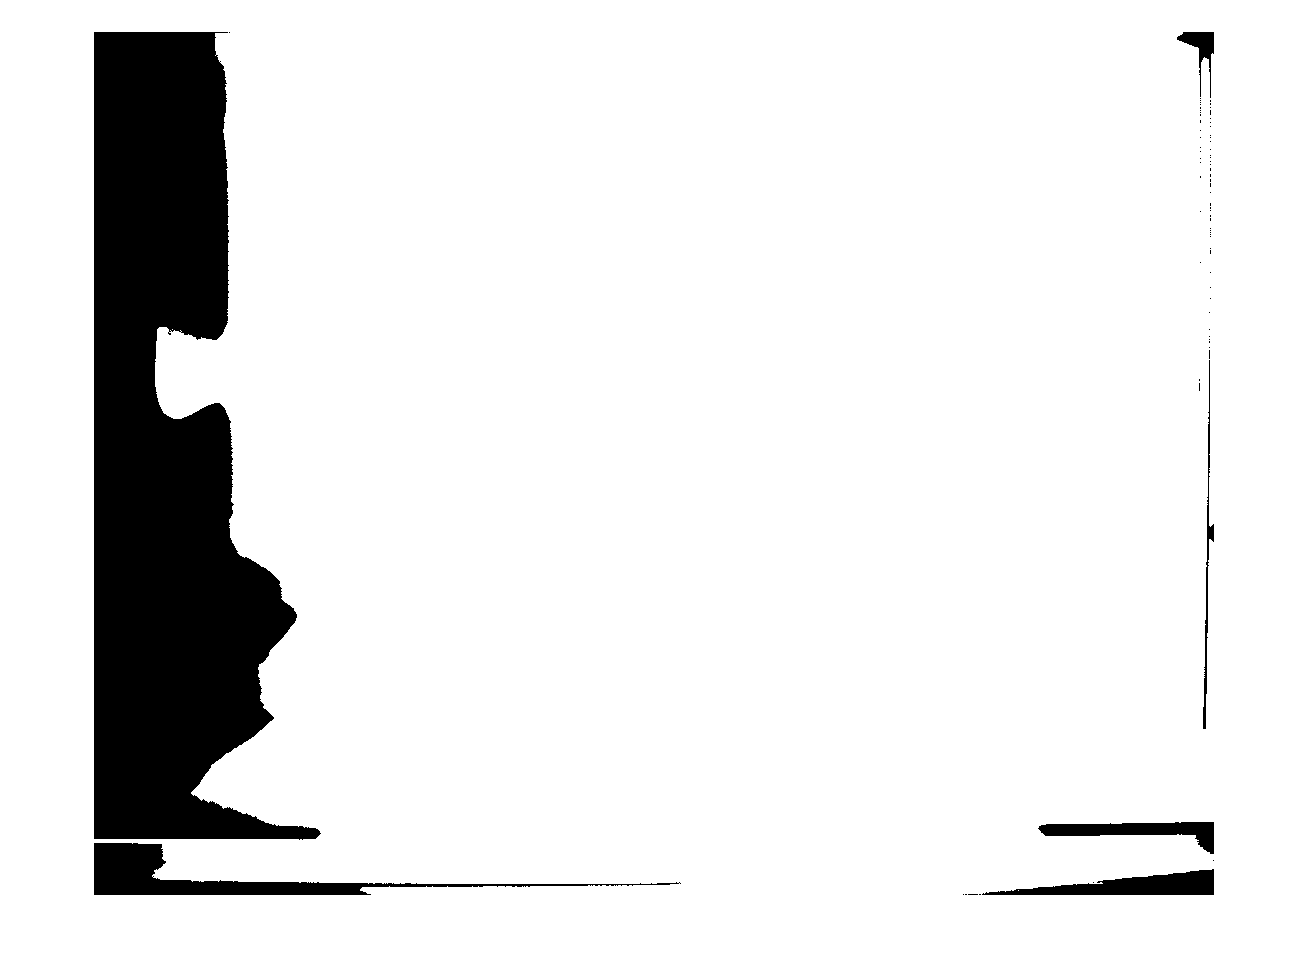


mask = zeros(size(frame));
mask(25:end-25,25:end-25) = 1;

bw = activecontour(frame,mask, 1000);

imshow(bw)